clear all;
out = sim("main.slx");

### Searching for referenced models in model 'main'.
### Found 1 model references to update.
### Starting serial model reference simulation build.
### Model reference simulation target for fp_model is up to date.

Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 6.0811s


signals = out.OutputData.signals;

sim_time = out.tout;
fft_signal = signals(1).values;
thd_signal = signals(2).values;
input_signal = signals(3).values;

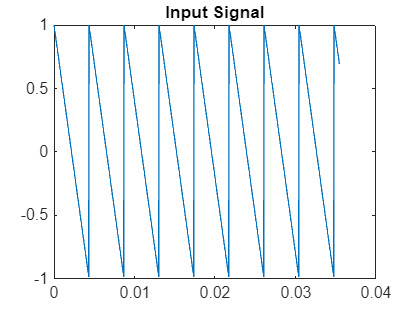

figure
plot(sim_time, input_signal);
title("Input Signal");

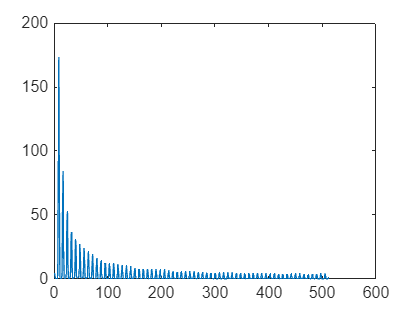



arbitrary_slice = signals(1).values(:, 1030);

lx = (length(arbitrary_slice));
half = ceil(lx/2);

figure
plot(abs(arbitrary_slice(1:half)))